## 编程与算法开发

### 9.1 目标：从算法到 MATLAB 编程

内容：编写函数，用序列法近似计算 π/4。

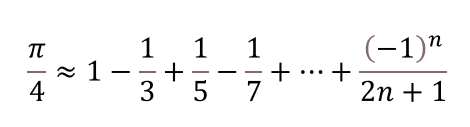

edit pio4sol

### 9.2 目标：MATLAB 编程技巧——预分配

内容：改写 9.1 中的函数，使用预分配。

edit pio4sol_pa

### 9.3 目标：MATLAB 编程技巧——向量化

内容：再次改写 9.1 中的函数，使用向量化实现。

edit pio4sol_vec

### 9.4 目标：MATLAB 编程技巧——向量化

内容：编写脚本，对比 9.1、9.2、9.3 中三个函数的运行效率。

edit pio4sol_comp
pio4sol_comp

(This computation could take some time...)
Time spent on each function:
pio4sol(10000000):      1.879355
pio4sol_pa(10000000):   0.544218
pio4sol_vec(10000000):  0.172467

pio4sol is 245.3% slower than pio4sol_pa.
pio4sol_pa is 215.5% slower than pio4sol_vec.



### 9.5 目标：用实时脚本交互式编程

内容：

1. 使用实时脚本可视化给定股票价格的移动均线；

2. 通过滑块调整移动平均参数，实时观察曲线变化。

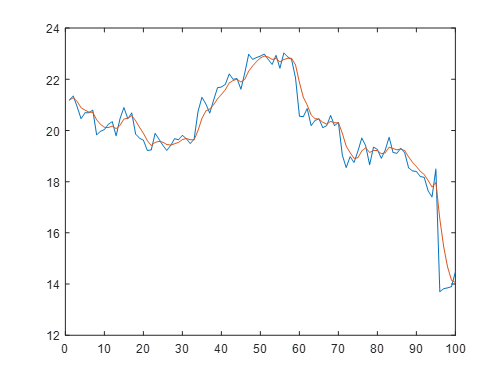

clear
load('stockData.mat')
type = 'linear';
windowSize = 5;
ma = movavg(stockData.price,type,windowSize)

ma =    21.1900
   21.2789
   21.1350
   20.8893
   20.7980
   20.7200
   20.7120
   20.4173
   20.2427
   20.1240


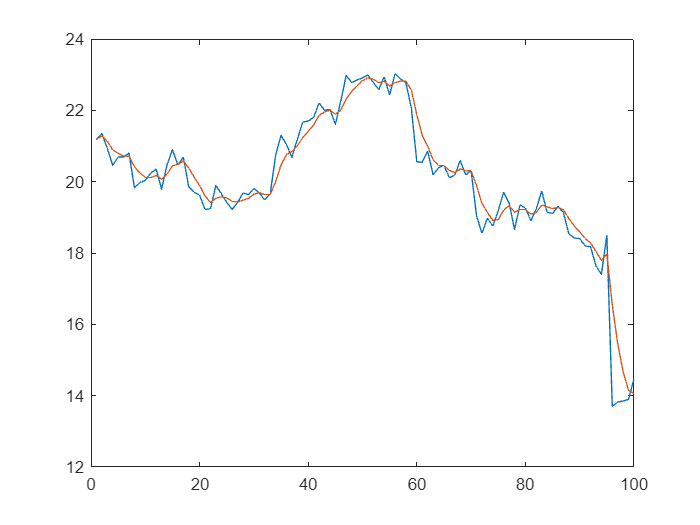

plot(stockData.price(1:100,1))
hold on
plot(ma(1:100,1))

### 练习

目标：基于 MATLAB App Designer 开发计算器 App

要求：

1. 至少实现加、减、乘、除四则运算；

2. 编译生成独立可执行文件，使其可在 MATLAB 外部独立运行。